# Diseño de controlador en cascada

close all
clear all
% Función de transferencia de velocidad del motor
G = tf(273,[1  4.112]) % Planta del laboratorio pasado


G =
 
     273
  ---------
  s + 4.112
 
Continuous-time transfer function.
Model Properties


%Parámetros de diseño
Tes = 1 % 0.8 s -> 2.4 s (3 veces más rápido)

Tes = 1

Mp = 0.4; % 4% 

Diseño del lazo interno

% Polos y ceros
sigma = 4/Tes;
wd = -pi*sigma/log(Mp);
s1 = -sigma+wd*1j

s1 = -4.0000 +13.7144i

s2 = -sigma-wd*1j

s2 = -4.0000 -13.7144i


so = -2.5*sigma

so = -10

% Controlador
Ti = -1/so

Ti = 0.1000


Gc_p = tf([1 1/Ti], [1 0])


Gc_p =
 
  s + 10
  ------
    s
 
Continuous-time transfer function.
Model Properties


Gol = Gc_p*G


Gol =
 
  273 s + 2730
  -------------
  s^2 + 4.112 s
 
Continuous-time transfer function.
Model Properties


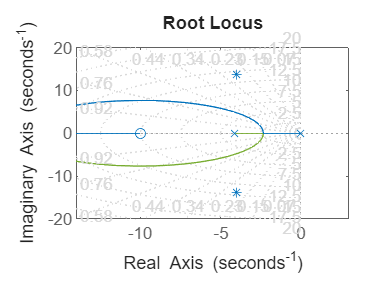

figure(1)
rlocus(Gol)
grid on
hold on 
plot([-sigma  -sigma],[wd  -wd],'*')
axis([-14 3 -20  20])
hold off

Kp=0.0597;
%En lazo cerrado
Glc = feedback(Kp*Gol,1)


Glc =
 
     16.3 s + 163
  -------------------
  s^2 + 20.41 s + 163
 
Continuous-time transfer function.
Model Properties


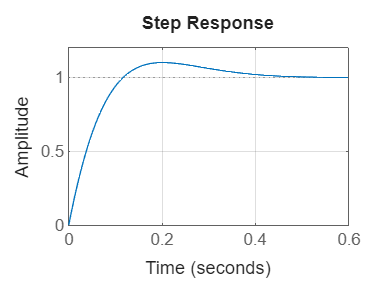


figure(2)
step(Glc);
grid on

% Tiempo de subida
Tr = 0.137 - 0.00352

Tr = 0.1335

Tr_ref = Tr/10

Tr_ref = 0.0133

T = 0.01 % 10 ms

T = 0.0100

Diseño de lazo externo

G2 = Glc*tf(1, [1 0]) % Lazo cerrado por integrador


G2 =
 
       16.3 s + 163
  -----------------------
  s^3 + 20.41 s^2 + 163 s
 
Continuous-time transfer function.
Model Properties



%Parámetros de diseño (lazo externo)
Tese = 2.5 

Tese = 2.5000

Mpe = 0.1; % 1% 

sigmae = 4/Tese;
wde = -pi*sigmae/log(Mpe);
se1 = -sigmae+wde*1j

se1 = -1.6000 + 2.1830i

se2 = -sigmae-wde*1j

se2 = -1.6000 - 2.1830i

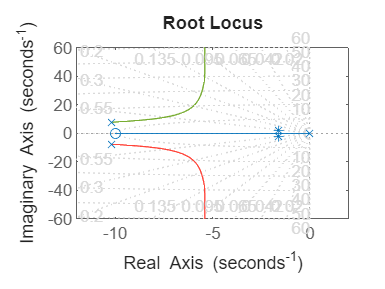



figure(3)
rlocus(G2)
grid on
hold on
plot([-sigmae  -sigmae],[wde  -wde],'*')
% axis([-14 3 -12  12])
hold off

Kpe = 1.61;
Glce = feedback(Kpe*G2, 1)


Glce =
 
           26.24 s + 262.4
  ---------------------------------
  s^3 + 20.41 s^2 + 189.2 s + 262.4
 
Continuous-time transfer function.
Model Properties


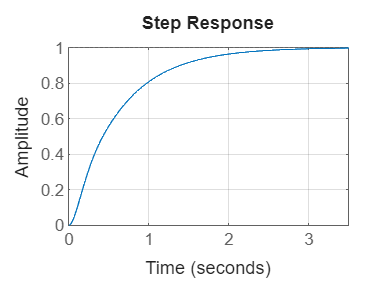

figure(4)
step(Glce)
grid on

Te = 3*T

Te = 0.0300

Resultados en XSpace

% Datos XSpace

% figure(5)
% plot(Datos_Xspace(:,1), Datos_Xspace(:,4))

Unrecognized function or variable 'Datos_Xspace'.

% title('Control de Posición - XSpace')
% ylabel('Posición (grados)')
% xlabel('Tiempo (ms)')
% grid on
